## Asse x 

## Dati

Jm_x=(14)*10^-6;        %Kg*m^2 n                 
Cm_x=1.7;               %N*m

Jp1_x=(0.2006)*10^-4;
Jp2_x=(0.5194)*10^-4;
Jp3_x=(0.1086)*10^-4;
m_x=1.55;               %[Kg]
%ho moltiplicato le giridezza sepecifiche per 10^3 per avere N/m
kcs1=(1.622)*10^7;      %[N/m]            rig. cinghia tratto 1 specifica ( da moltiplicare per spessore e dividere per lunghezza)
w1=(9)*10^-3;           %[m]                   spessore cinghia 1 tratto
kcs2=(2.34)*10^7;       %[N/m]
w2=(10)*10^-3;          %[m]


d1=(23.87*10^-3);     %[m]
d2=(54.12*10^-3);     %[m]
d3=(25.46*10^-3);     %[m]

r1=(23.87*10^-3)/2;     %[m]
r2=(54.12*10^-3)/2;     %[m]
r3=(25.46*10^-3)/2;     %[m]

a1=(76)*10^-3;          %[m] 
a2=(1275)*10^-3;        %[m]

c1=0;
c2=0;
c3=0;
c4=0;


## Calcolo lunghezze tratti di cinghia

L1_tot=(2*a1)+(pi/2)*(d1+d2)+((d1-d2)^2)/(4*a1);
L1_intermedio=L1_tot-pi*(r1+r2);
L1=L1_intermedio/2

L1 = 0.0775



L2_tot=(2*a2)+(pi/2)*(d3+d3)+((d3-d3)^2)/(4*a2);
L2_intermedio=L2_tot-pi*(r3+r3);
L2=L2_intermedio/2

L2 = 1.2750


k1=kcs1*(w1/L1);
k2=kcs2*2*(w2/L2);
k3=k2;
k4=kcs2*(w2/L2);

## Calcolo matrici M, D, K,F

disp('matrice masse')

matrice masse



M=[Jm_x+Jp1_x, 0, 0, 0;  %:theta1
   0, Jp2_x+Jp3_x, 0, 0; %:theta2
   0, 0, Jp3_x, 0;     %:theta3
   0, 0, 0, m_x        %:x
   ]

M =     0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0000         0
         0         0         0    1.5500



disp('matrice rigidezze')

matrice rigidezze



K = [2*k1*(r1^2) , -2*k1*r2*r1  ,                0,           0;
  -2*k1*r2*r1     , (2*k1*(r2^2))+(k2+k4)*(r3^2)   ,    -k4*(r3^2)  ,             -k2*r3;
   0              ,  -k4*(r3^2) ,            (k3+k4)*(r3^2)       ,           -k3*(r3);
   0 ,                       -k2*r3 ,                        -k3*(r3) ,                k3+k2]

K = 	1.0e+05 *

    0.0054   -0.0122         0         0
   -0.0122    0.0285   -0.0003   -0.0467
         0   -0.0003    0.0009   -0.0467
         0   -0.0467   -0.0467    7.3412



disp('matrice smorzamenti')

matrice smorzamenti



C=[2*c1*(r1^2),               -2*c1*r2*r1,                    0,                      0;
  -2*c1*r2*r1,              (2*c1*(r2^2))+(c2+c4)*(r3^2),      -c4*(r3^2),             -c2*r3;
   0,                       -c4*(r3^2),                      (c3+c4)*(r3^2),           -c3*(r3);
   0,                       -c2*r3,                        -c3*(r3),                c3+c2]

C =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


%F = [Cm_x;0;0;0] %forcing force on the 4rd coordinate
F = [Cm_x;0;0;0]

F =     1.7000
         0
         0
         0


## CALCOLO AUTOVALORI ED AUTOVETTORI


disp('V contiene gli autovettori, "D" contieene gli autovalori su diagonale')

V contiene gli autovettori, "D" contieene gli autovalori su diagonale


%[v,d]=eig(inv(M)*K); % le colonne di v sono corrispondenti  POCO ACCURATO
%mm=K/M;
%[v,d]=eig(mm); % le colonne di v sono corrispondenti
% the eigenvalues are the nat. freq. at the power of 2
%disp('Matrice v, ogni colonna equivale ad un autovettore: ')
%disp(v);
%disp('Matrice d, matrice diagonale contente gli autovalori: ')
%disp(d);
[V, D]=show_mode(M,K); %si mostrano i vari modi di vibrare

mode 1 - natural frequency w = 0.000028 [rad/s] - 0.000004 [Hz] 
A1 = 1.000000 
A2 = 0.441057 
A3 = 0.441057 
A4 = 0.005615 
mode 2 - natural frequency w = 798.486376 [rad/s] - 127.083054 [Hz] 
A1 = 1.000000 
A2 = 0.423207 
A3 = -0.141325 
A4 = -0.005183 
mode 3 - natural frequency w = 2898.206577 [rad/s] - 461.263903 [Hz] 
A1 = 0.037865 
A2 = 0.007796 
A3 = -1.000000 
A4 = 0.000377 
mode 4 - natural frequency w = 7794.223856 [rad/s] - 1240.489254 [Hz] 
A1 = -0.793829 
A2 = 1.000000 
A3 = -0.051742 
A4 = -0.000047 



%for i= 1:4
 %  fscala = max(abs(v(:,i)));
 %  v(:,i)=v(:,i)./fscala;
%end


## Metodo di normalizzazione rispetto alla matrice delle masse M

%{
pii=zeros(4,1);
pii_quadro=zeros(4,1);
W_i= zeros(4,1);
for ti=1:4
    
    pii_quadro(ti,1)=(v(:,ti)'*M*v(:,ti))\1;
    pii(ti,1)=sqrt(pii_quadro(ti,1));
    W_i(ti,1)=sqrt(d(ti,ti));
end
%adesso ho lo scalare pi che rende unitaria la rispettiva massa modale

%matrice massa modale
%M_norm=zeros(4,4);
K_norm=zeros(4,4);
M_norm=zeros(4,4);
%mi interessano solo gli ele
for ti=1:4
    M_norm(ti,ti)=pii(ti)*v(:,ti)'*M*pii(ti)*v(:,ti);
                    %rigidezza_modale(ti,ti)=v(:,ti)'*K*v(:,ti);
                    %M_norm(ti,ti)= massa_modale(ti,ti)/pii(ti)^2;
                    %K_norm(ti,ti)=rigidezza_modale(ti,ti)/M_norm(ti,ti);
    K_norm(ti,ti)= d(ti,ti);
end


%}

## ipotesi di smorzamento proporzionale, quindi vale la relazione:

fi'*C*fi= a*(massa_modale)+b(rigidezza_modale)= smorzamento_modale

dove      per i=j  ---> ci= 2*smorzamento*pulsazione_i

              per i!=j ---> ci=0

definizione coeffieciente di smorzamento

z=0.7

z = 0.7000

C_mx=zeros(4,4);

%for ti=1:4
    %C_mx(ti,ti)= 2*massa_modale(ti,ti)*z_smorzamento*W_i(ti,1);
  %  C_mx(ti,ti)= 2*z*W_i(ti,1);
%end

%M_norm,K_norm,C_mx
%C_0 = inv(v')*C_mx*inv(v)
%
%F_modale = v'*F;


## medoto di normalizzazione della componente unitaria 

massa_modale=zeros(4,4);
rigidezza_modale=zeros(4,4);
for ti=1:4
    massa_modale(ti,ti) = (V(:,ti)')*M*V(:,ti);
    rigidezza_modale(ti,ti) = (V(:,ti)')*K*V(:,ti);
end
rigidezza_modale,massa_modale

rigidezza_modale = 	1.0e+03 *

   -0.0000         0         0         0
         0    0.0463         0         0
         0         0    0.0934         0
         0         0         0    3.1362


massa_modale = 	1.0e+-4 *

    0.7001         0         0         0
         0    0.7269         0         0
         0         0    0.1112         0
         0         0         0    0.5163


C_mx1=zeros(4,4);

for ti=1:4
    C_mx1(ti,ti)=2*z*sqrt(massa_modale(ti,ti)*rigidezza_modale(ti,ti));
end
C_mx1

C_mx1 =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0813 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0451 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.5633 + 0.0000i



C_1 = ((V')^-1)*C_mx1*((V)^-1)

C_1 = 	1.0e+02 *

   0.0011 + 0.0000i  -0.0021 + 0.0000i  -0.0000 + 0.0000i  -0.0298 + 0.0000i
  -0.0021 + 0.0000i   0.0052 + 0.0000i  -0.0001 + 0.0000i  -0.0323 + 0.0000i
  -0.0000 + 0.0000i  -0.0001 + 0.0000i   0.0004 + 0.0000i  -0.0215 + 0.0000i
  -0.0298 + 0.0000i  -0.0323 + 0.0000i  -0.0215 + 0.0000i   9.5311 + 0.0000i



C_controllo =diag( ((V'))*C_1*(V))

C_controllo =   -0.0000 + 0.0000i
   0.0813 - 0.0000i
   0.0451 - 0.0000i
   0.5633 - 0.0000i


F_modale1 = V'*F;


## Confronto della matrici C ricavate dai due metodi:

%disp('C dalla normalizzazione della massa:')
%C_0
%disp('C dalla normalizzazione degli autovettori:')
%C_1


## Tracciamento dei grafici:


$$\left(
-\Omega^2M + 1j\Omega C +K
\right)
X = F$$



%thehta1,theta2,theta3,theta4,x,
x0=[0; 0; 0; L2/2] %inital condition on position

x0 =          0
         0
         0
    0.6375


dotx0=[0; 0; 0; 0]; %initial condition con speed


%evaluation of the coeffcient of the linear comb. of modes
coeff=coeff_free_vib(V,D,x0,dotx0);
disp('coefficients of the linear combination')

coefficients of the linear combination


disp(coeff)

         0
   67.2361
         0
  -64.3411
         0
   33.5188
         0
   -0.7104




disp('time response of the two coordinates')

time response of the two coordinates



%vector with the frequencies at wich evaluete the solutions (200 solutions)
wmax= 8000;
Om=-0:(2*wmax)/200:2*wmax;

%solves and plots the amplitude of vibrations of the coordinates
disp('C nulla   ')

C nulla   


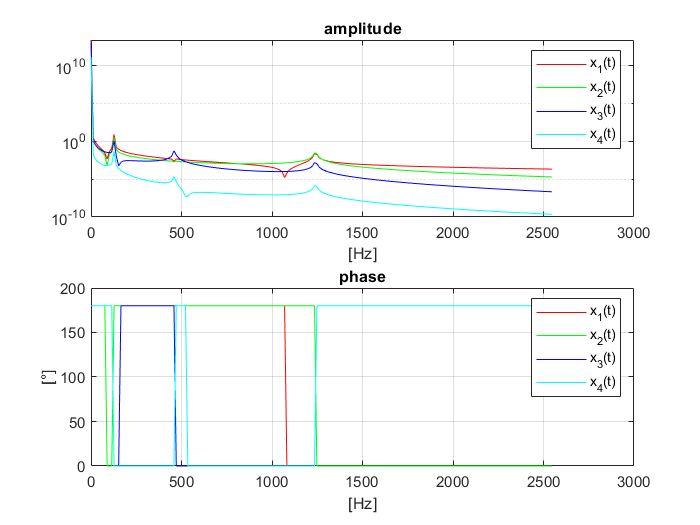

plotForcedDumped(M,C,K,F,Om)



%disp('Grafici con C ricavata dalla normalizzazione della masse:')
%plotForcedDumped(M,C_0,K,F,Om)

disp('Grafici con C ricavata dalla normalizzazione degli autovettori:')

Grafici con C ricavata dalla normalizzazione degli autovettori:


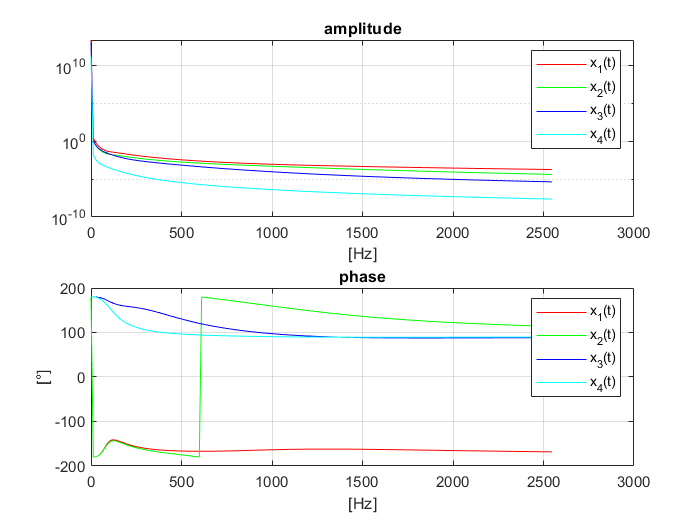

plotForcedDumped(M,C_1,K,F,Om)